# Design of FIR Filters (100 Points)

Welcome to Lab 3!

In this lab, you will design FIR filters. Refer to the below diagram for the lab.  

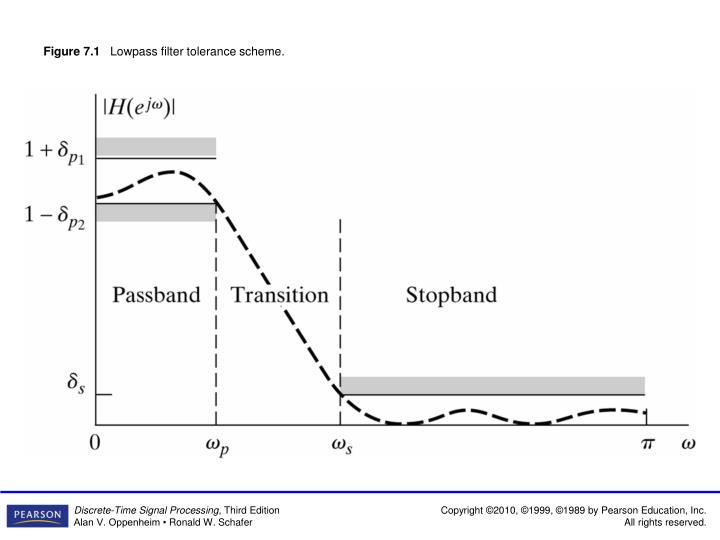

We will design FIR filters satisfying the following specifications: 

- 
$$\omega_p =0.4\pi
$$


- 
$$\omega_s = 0.6\pi
$$
 

- 
$$\delta_{p_1}=\delta_{p_2}=0.01, \;\;\delta_s=0.01$$


## Windowing Method (50 Points)

Now, using the Kaiser window, come up with a window-based FIR filter with the above specifications (presented just after the first image of the notebook)

For theoretical understanding, see (i) page 499, Example 7.8 of the Second Edition of the textbook, or (ii) page 569, Section 6.1 of Third Edition of your textbook.  

- From your theoretical understanding, what is the filter order (approx)?  $M=\frac{A-8}{2\ldotp 285\Delta \;\omega \;\;}=\frac{\left(-20{\;\log }_{10} \delta \right)-8}{2\ldotp 285\;\left(\omega_s -\omega_p \right)}=\frac{40-8}{2\ldotp 285\times 0\ldotp 2\pi \;}=22\ldotp 29$. M needs to be integer so take M=23.

- Open "filterDesigner" tool (you can open it by typing *filterDesigner* in the Matlab command window as shown below.)

                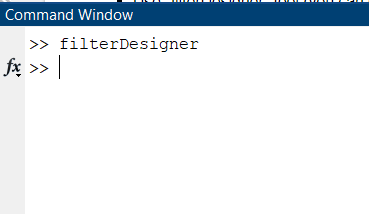

       Open the below view. Here you can specify frequency and magnitude specifications. 

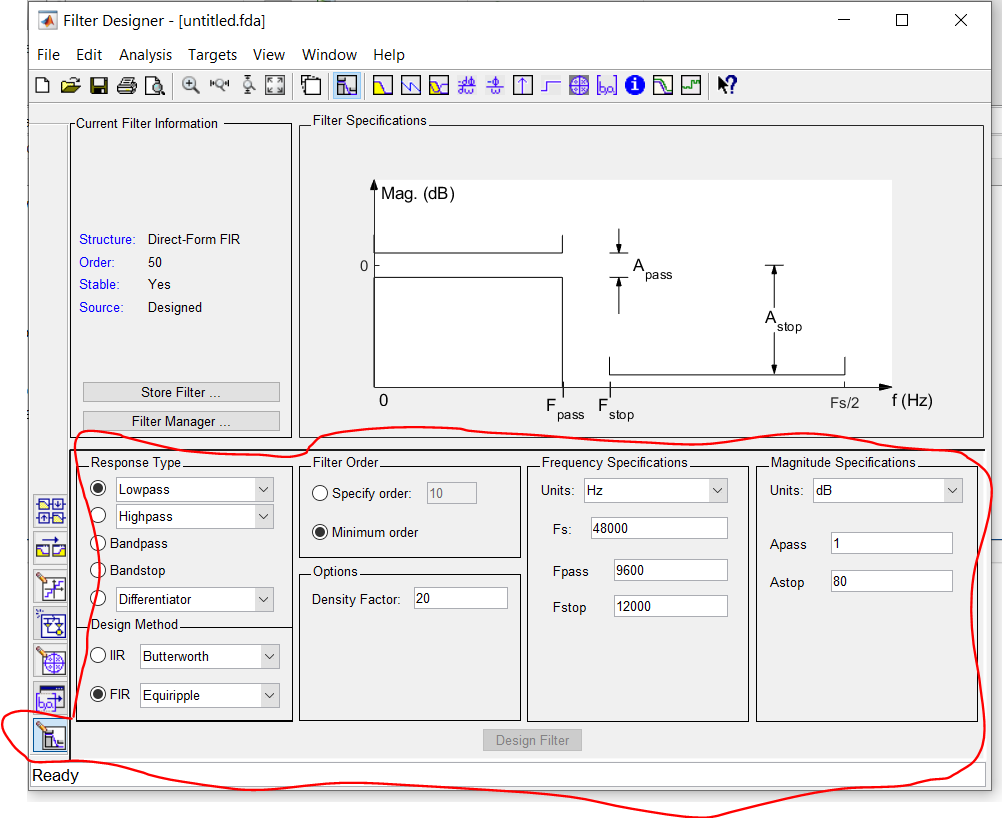

-   Obtain the coefficients of the filter. Write down the coefficients below. 

% ASSIGN THE FILTER COEFFICIENTS TO "b". 
b = [-0.002907211955384275854641362712982299854;
    -0.004903665350658096937219720956591118011;
     0.007556835867128868303166377984325663419;
     0.011022695479796449855025564090738043888;
    -0.015522540177083104726007967144596477738;
    -0.021399197607360729428416235009535739664;
     0.029235890996987257128836290576145984232;
     0.040134591714861472810937925714824814349;
    -0.056471920114176024640961770728608826175;
    -0.084468388232154023587128222061437554657;
     0.147031071648377920091377291100798174739;
     0.450691837729664368517035200056852772832;
     0.450691837729664368517035200056852772832;
     0.147031071648377920091377291100798174739;
    -0.084468388232154023587128222061437554657;
    -0.056471920114176024640961770728608826175;
     0.040134591714861472810937925714824814349;
     0.029235890996987257128836290576145984232;
    -0.021399197607360729428416235009535739664;
    -0.015522540177083104726007967144596477738;
     0.011022695479796449855025564090738043888;
     0.007556835867128868303166377984325663419;
    -0.004903665350658096937219720956591118011;
    -0.002907211955384275854641362712982299854];

- Does the number of entries in $b$ correspond to the above theoretically obtained filter order?

           * ANSWER : Yes.*

*                               Theoretical order was calculated to be 23 and we got 24 coefficients which suggests order to be (24-1) = 23.*

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.

           * ANSWER :*

            **pole-zero plot**: There are 23 zeros and 1 pole. 11 zeros are on unit circle. The other zeros appear as complex conjugates as well as inverses. The pole is at 0.

            **magnitude and phase response**: The max amplitude is observed at 0.37pi and decreases till 0.6pi, we can see side lobe height is atmost delta. The phase decreases at a constant rate which suggests that the filter is a GLP system.

            **group delay plot**: The group delay plot is constant with a value of 11.5.

## Min-Max Method (50 Points): 

You already know that the the FIR filter designed using the windowing method has minimimum mean squared error with respect to the ideal filter response. Now, we will design a filter which minimizes the maximum error with respect to the ideal filter. Now watch optionally watch [https://drive.google.com/file/d/1oIeN7SOJp_EZcXk_god2Ze9BxSz7iUyr/view?usp=sharing](https://drive.google.com/file/d/1oIeN7SOJp_EZcXk_god2Ze9BxSz7iUyr/view?usp=sharing)  to understand the theory behind the optimal min-max FIR filter design method. Design an FIR filter satisfying the  specifications presented just after the first image of the notebook using  [firpm](https://in.mathworks.com/help/signal/ref/firpm.html).

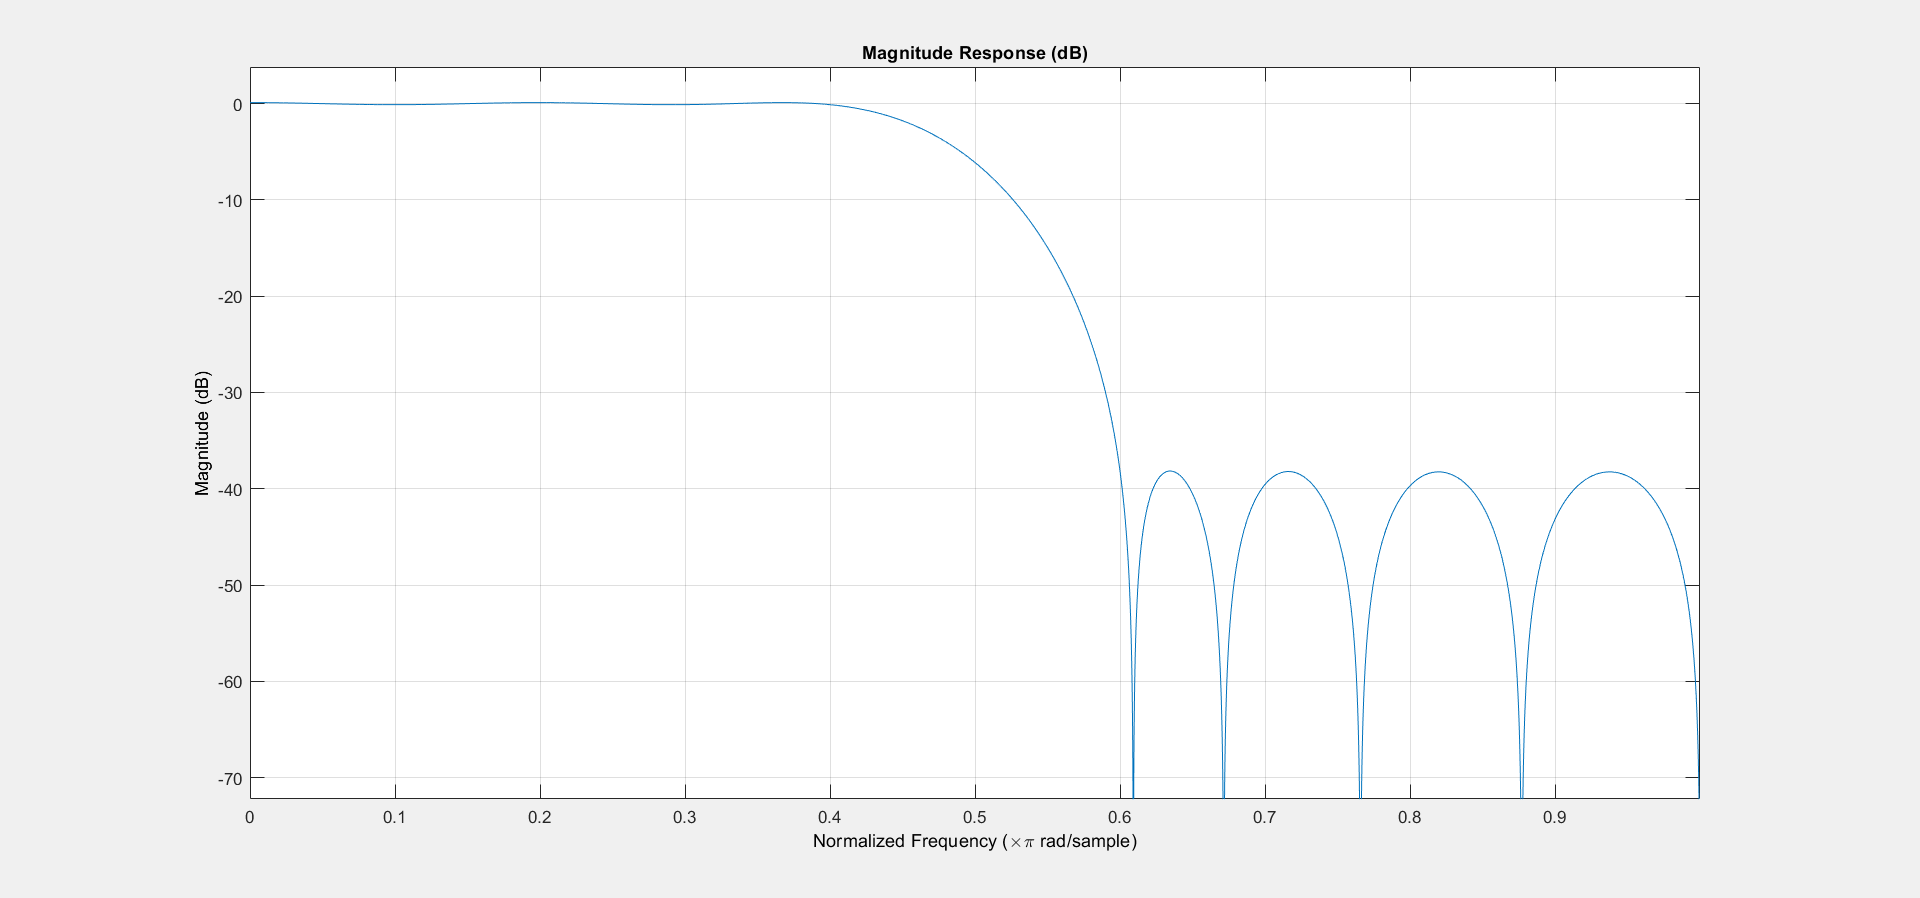

% WRITE YOUR CODE HERE
[n,fo,ao,w] = firpmord([9600 14400],[1 0],[0.01 0.01],48000);
b = firpm(n,fo,ao,w);
fvtool(b,1);

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.      

           * ANSWER:*

            **pole-zero plot**: There are 19 zeros and 1 pole. 9 zeros are on unit circle. The other zeros appear as complex conjugates as well as inverses. The pole is at 0.

            **magnitude and phase response**: The max amplitude is observed at 0.37pi and decreases till 0.6pi, we can see side lobe height is atmost delta. The phase decreases at a constant rate which suggests that the filter is a GLP system.

            **group delay plot**: The group delay plot is constant with a value of 9.5.

- Give a comparison with the filter obtained using the windowing method above.  

           * ANSWER*

            Kaiser window: Magnitude response has less ripples in pass-band and order of filter is 23

            Parks-McClellan optimal FIR filter: Magnitude response has more ripples in stop-band and order of filter is 19

### Thank you!